%load labelled images for use as ground truth data
load IrisGroundTruth.mat
%Assign ground truth images 
[images, boxLabels] = objectDetectorTrainingData(gTruth);
%list of files in images
imgFiles = images.Files;
%combine images with labels
imgsLabelled = combine(images,boxLabels);

%Create object detector (ACF-based)
detectorACF = trainACFObjectDetector(imgsLabelled)

ACF Object Detector Training
The training will take 4 stages. The model size is 20x21.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 69 positive examples and 345 negative examples...Completed.
The trained classifier has 47 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 340 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 69 positive examples and 345 negative examples...Completed.
The trained classifier has 144 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 273 new negative examples for training.
Compute aggregated channel features...Com

detectorACF =   acfObjectDetector with properties:

             ModelName: 'iris'
    ObjectTrainingSize: [20 21]
       NumWeakLearners: 289


%define some box sizes for use in object detection
anchorBoxes = {[10,10];
               [25,25];
               [50,50];};

%load pre-trained detector
trainedYOLO = yolov4ObjectDetector('csp-darknet53-coco', {'iris'}, anchorBoxes, 'InputSize', [352,640,3]);

%define training options
options = trainingOptions('sgdm', 'InitialLearnRate', 0.001, 'MaxEpochs', 20, 'BatchNormalizationStatistics', 'moving' ...
    ,'ResetInputNormalization', false, 'MiniBatchSize', 8);

%create object detector (YOLO-based)
detectorYOLO = trainYOLOv4ObjectDetector(imgsLabelled,trainedYOLO, options)

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* iris

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
     10         50         00:20:46        0.001         13.283   
     20         100        00:40:40        0.001         12.944   

*************************************************************************
Detector training complete.
*************************************************************************



detectorYOLO =   yolov4ObjectDetector with properties:

        Network: [1×1 dlnetwork]
    AnchorBoxes: {3×1 cell}
     ClassNames: {'iris'}
      InputSize: [352 640 3]
      ModelName: 'csp-darknet53-coco'


X = 21 

X = 21

%get boxes and scores
[box,score] = detect(detectorACF,imread(imgFiles{X}))

box = 2×4 single matrix
1.0e+03 *

    0.9155    0.4181    0.0210    0.0207
    1.0178    0.4193    0.0231    0.0208


score = 2×1 single column vector
    0.9979
    0.9833


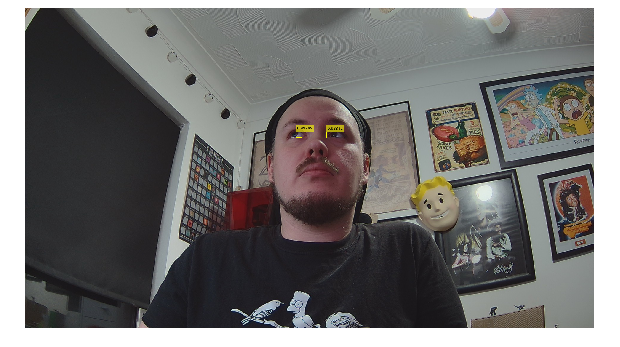

%show image with boxes and scores
imageScored = insertObjectAnnotation(imread(imgFiles{X}),"rectangle",box,score);
imshow(imageScored);


%HANDY
%im = imread(imgFiles{X});
%bb = boxLabels.LabelData{X,1};
%im = insertObjectAnnotation(im,"rectangle",bb,"Iris");
%imshow(im);